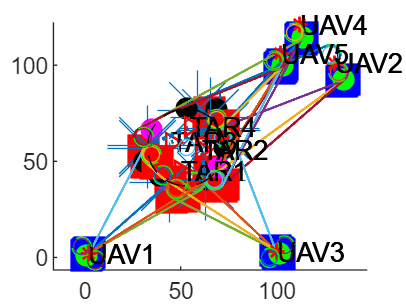

clear all;
clc;
close all;
%% 设置初始参数
Uav = [2,2,45*pi/180;...
    130,101,23*pi/180;...
    100,3,130*pi/180;...
    %     4,105,200*pi/180;...
    112,121,324*pi/180;...
    102,106,316*pi/180];%UAV的初始参数，X位置，Y位置，速度方向
Target = [50,45,45*pi/180;...
    61,56,96*pi/180;...
    45,60,196*pi/180;...
    55,68,24*pi/180];%TAR的初始参数，X位置，Y位置，可攻击方向
R_dubins = 5;%最小转弯半径
R_max = 12;%转弯半径上限
R_step = 0.3;%半径递增步长
%求取目标中心位置（X_obs,Y_obs）：
[count_target, ~] = size(Target);
X_obs = Target(:, 1)' * ones(count_target,1) / count_target;
Y_obs = Target(:, 2)' * ones(count_target,1) / count_target;
C_obs =[X_obs,Y_obs,20];%障碍圆的参数 X位置，Y位置，半径
step = 0.1;%步长
%% 计算代价值
[P,P1] = size(Uav);
[Q,Q1] = size(Target);
for i=1:P
    for j=1:Q
        figure(1);
        hold on;
        param_all(i,j) = Dubins_Run(Uav(i,:),Target(j,:),R_dubins,C_obs,step);
        cost(i,j) = param_all(i,j).Length;
    end
end
[assignments, ~,~] = auction(cost, 0.1);

for i=1:5
    for j=1:4
        DrawD(param_all(i,j),i,j)
    end
end

hold off;

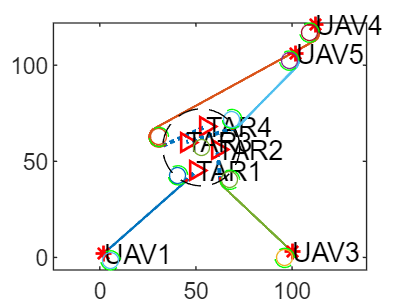

%% 绘图
for i=1:P
    if assignments(2,i)~=0
        DrawD(param_all(i,assignments(2,i)),i, assignments(2,i));
    end
end

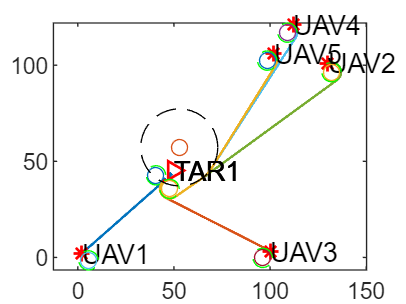



figure(3)
for i=1:5
    DrawD(param_all(i,1),i,1)
end

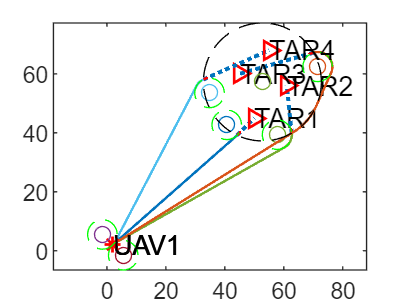

figure(4)
for j=1:4
    DrawD(param_all(1,j),1,j)
end